# 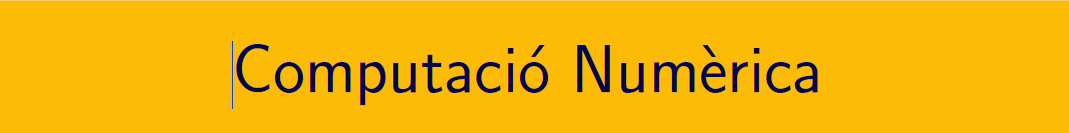

`================================================================================`

# Pràctica 12. Equacions diferencials ordinàries (III).

`Document preparat per M. Àngela Grau Gotés - 23 de maig de 2022`

## Mètodes multipas

## `Exercici  `$y^{\prime}(t)=y(t)+t^2\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

`Solució analítica`

clearvars
syms y(t)
eqn = diff(y,t) == y+t^2;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{t}-2\,t-t^{2}-2$$

`La solució es pot respresentar a l'interval [0,1]`

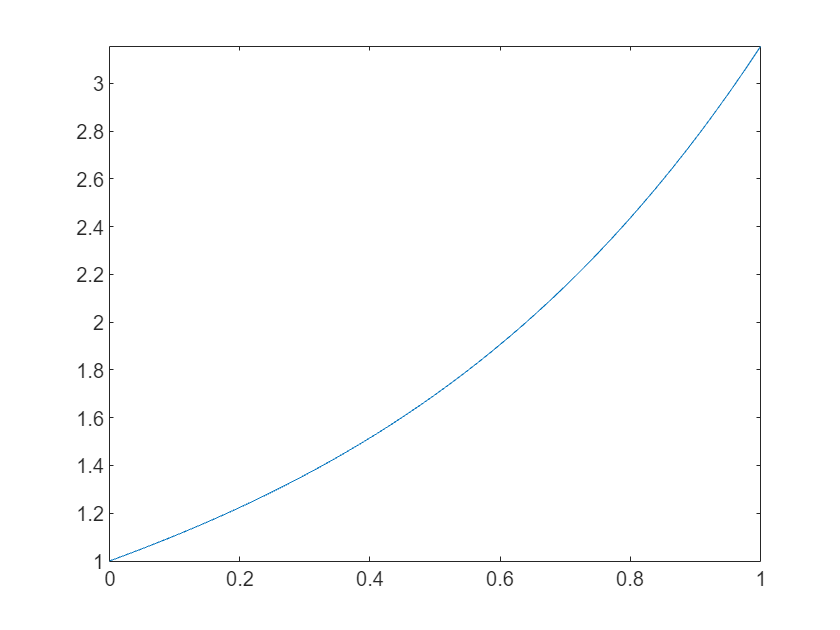

fplot(ySol,[0,1])

## `Solucions aproximades numèricament O(h^4)`

- `Mètode RK4`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;                % y(b) = ...
f = @(t,y)(y-t.^2);



- `Mètode Adams-Moulton`

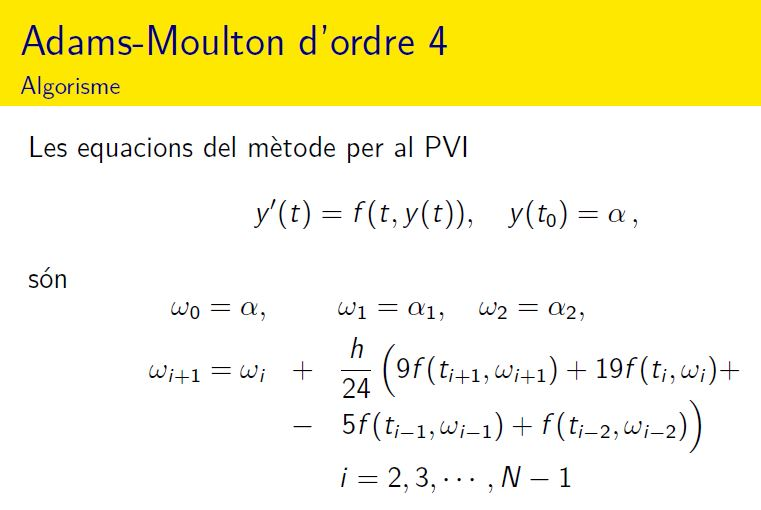

- `Mètode Adams-Moulton, els primers calculats exactament`

% Mètode de  Adams-Basforth
% iniciem per valor exacte
w(1) = alpha;
h = 0.1;
t=[a:h:b];
N=length(t);
w(1) = alpha;
w2 = RK4(f, a, b, h, alpha);
w(2) = w2(2);
w(3) = w2(3);
for i=3:N-1
    a1 = 19*f(t(i),w(i)); 
    a2 = -5*f(t(i-1),w(i-1));
    a3 =    f(t(i-2),w(i-2));
    F = @(z)(z-w(i)-h/24*(9*f(t(i+1),z)+a1+a2+a3));
    w(i+1) = fzero(F,w(i));
end
wSol = w;

E = abs(double(ySol(t))-wSol);
disp(table(t',double(ySol(t))',wSol',E','VariableNames',{'t','Y','Y_AB','E_{local}'}))

     t            Y                  Y_AB               E_{local}      
    ___    ________________    ________________    ____________________
      0                   1                   1                       0
    0.1    1.10551275422694    1.10482895833333    0.000683795893609673
    0.2    1.22420827448051    1.21859699057205     0.00561128390846077
    0.3    1.35957642272801    1.34014058773374      0.0194358349942694
    0.4    1.51547409292381     1.4681742693875       0.047299823536314
    0.5    1.69616381210038     1.6012771853821      0.0948866267182846
    0.6    1.90635640117153    1.73787904872191       0.168477352449622
    0.7    2.15125812241143    1.87624442407554       0.275013698335887
    0.8     2.4366227854774    2.01445535834346       0.422167427133948
    0.9    2.76880933347085    2.15039218501861       0.618417148452238


- `Mètode Adams-Moulton, els primers calculats per RK4`

% Mètode de  Adams-Basforth
% iniciem per RK4



function  w  = RK4( f,a,b,h,alpha )
% Mètode RK4
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1=h*f(t(i),w(i));
        k2=h*f(t(i)+h/2,w(i)+k1/2);
        k3=h*f(t(i)+h/2,w(i)+k2/2);
        k4=h*f(t(i+1),w(i)+k3);
        w(i+1)=w(i)+(k1+2*k2+2*k3+k4)/6;
    end
end
%---------------------------------------
function [ w ] = Euler( f,a,b,h,alpha )
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
    for i=1:N-1
        w(i+1)=w(i)+h*f(t(i),w(i));
    end
end
%---------------------------------------